## Stock Market Prediction Algorithm

### Introduction

A machine learning model in MATLAB that predicts stock market prices based on historical data. It utilises time seriea analysis and neural networks to evelulate the effectiveness in price prediction.

### Data Importation

%Loading data from csv files
warning('off', 'all');
folderPath = './data'; % Update folder path
filePattern = fullfile(folderPath, '*.csv');
csvFiles = dir(filePattern);

allData = cell(length(csvFiles), 1);

for k = 1:length(csvFiles)
    baseFileName = csvFiles(k).name;
    fullFileName = fullfile(folderPath, baseFileName);
    allData{k} = readtable(fullFileName);
end
allData

allData = 20×1 cell array
    {2516×7 table}
    {2515×7 table}
    {2516×7 table}
    {2516×7 table}
    {2515×7 table}
    {2516×7 table}
    {2509×7 table}
    {2515×7 table}
    {2516×7 table}
    {2516×7 table}
    {2515×7 table}
    {2515×7 table}
    {2516×7 table}
    {2515×7 table}
    {2515×7 table}
    {2516×7 table}



% Loading validation data from csv files
validationFolderPath = './validation'; % Update validation folder path
validationFilePattern = fullfile(validationFolderPath, '*.csv');
validationCsvFiles = dir(validationFilePattern);

validationData = cell(length(validationCsvFiles), 1);

for k = 1:length(validationCsvFiles)
    baseFileName = validationCsvFiles(k).name;
    fullFileName = fullfile(validationFolderPath, baseFileName);
    validationData{k} = readtable(fullFileName);
end
validationData

validationData = 20×1 cell array
    {19×7 table}
    {19×7 table}
    {19×7 table}
    {19×7 table}
    {19×7 table}
    {19×7 table}
    {19×7 table}
    {19×7 table}
    {19×7 table}
    {19×7 table}
    {20×7 table}
    {19×7 table}
    {19×7 table}
    {19×7 table}
    {19×7 table}
    {19×7 table}


This MATLAB script disables warnings, specifies a folder path (`folderPath`) where CSV files are located, constructs a file pattern to match CSV files, lists all CSV files in the folder, initializes a cell array (`allData`) to store tables, and iteratively loads each CSV file into a table using `readtable`, storing them in `allData`.

### Data Cleaning

%checking for missing values

warning('off', 'all');
for n = 1:length(allData)
    data = allData{n};  % Retrieve the table for the n-th CSV file
    missingValues = any(ismissing(data), 'all');  % Check for missing values across all columns and rows
    if missingValues % Print if there are missing values
        missingValues
        disp(n)
    end
end

This MATLAB snippet begins by suppressing all warnings for cleaner output. It retrieves a table (`data`) from the cell array `allData`, corresponding to a CSV file. It then checks for missing values (`NaN`, `undefined`, or empty cells) across all rows and columns using the `ismissing` function. The result, stored in `missingValues`, is printed to indicate if any missing values were found. In this case, the result is zero, confirming that there are no missing values in the dataset. This script is useful for quickly verifying data integrity before further analysis or processing in MATLAB, ensuring datasets are complete and ready for use.

### Data Normalization

%% Normalizing the  data
for k = 1:length(allData)
    allData{k}{:, 2:end} = normalize(allData{k}{:, 2:end}, 'range'); % Assuming the first column is a date or similar identifier
end
allData{1}

ans = 2516×7 table
       Date         Open         High          Low        Close      AdjClose     Volume 
    __________    _________    _________    _________    ________    ________    ________

    2014-07-01     0.012229     0.011391      0.01239    0.012395    0.012395    0.090484
    2014-07-02     0.012324      0.01179     0.012632    0.012967    0.012967    0.063024
    2014-07-03     0.012937     0.012012     0.012245     0.01249     0.01249    0.069285
    2014-07-07     0.012324     0.011613     0.012584    0.012586    0.012586    0.065113
    2014-07-08     0.012418     0.011569     0.012052    0.012395    0.012395     0.12824
    2014-07-09     0.012229     0.011524     0.012536    0.012443    0.012443    0.056797
    2014-07-10     0.0

This MATLAB snippet normalizes the data in each table within the cell array `allData`. It iterates through each table and applies the `normalize` function with the 'range' method to all columns except the first one, scaling the data to the range [0, 1]. The first column is assumed to be an identifier, such as a date, and is therefore excluded from normalization. After normalizing all the tables, the code displays the normalized data for the first table in `allData`, ensuring that the numerical data is uniformly scaled across the dataset while preserving the integrity of the identifier column. This process helps prepare the data for further analysis or modeling in a standardized format

### Time Series of Closing Prices

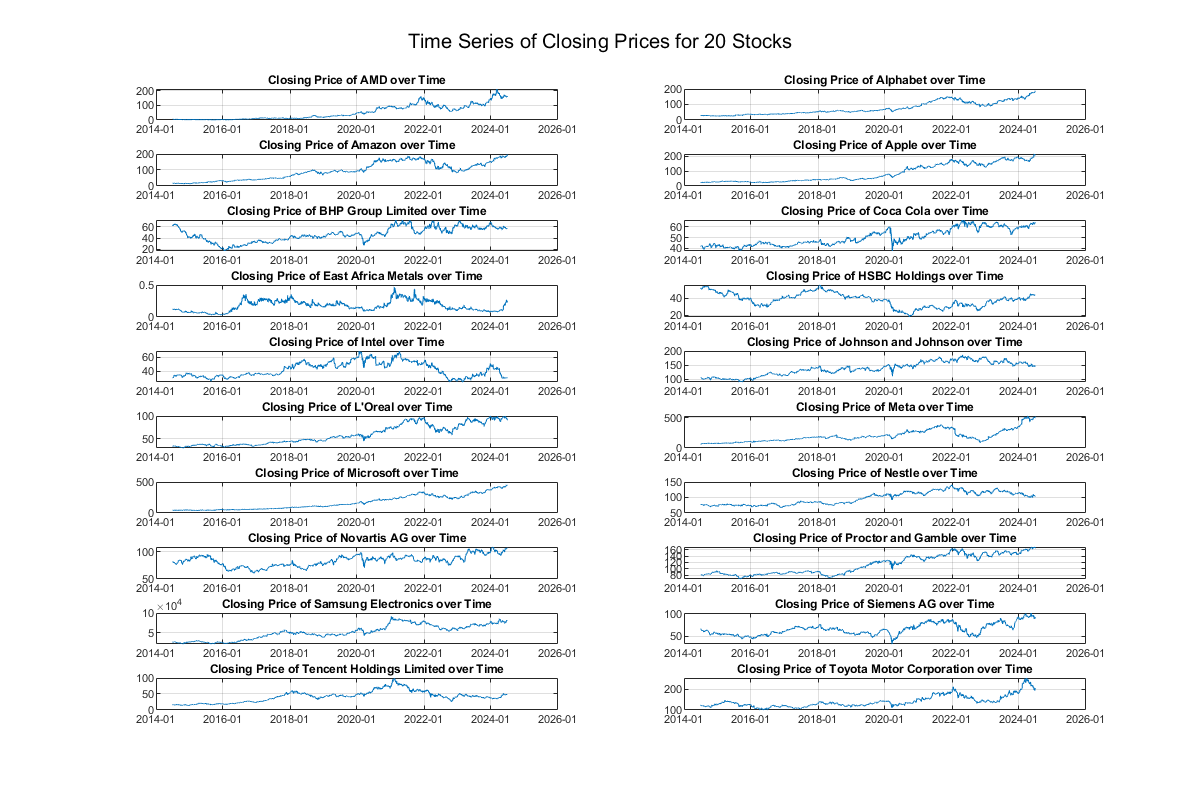

%Time series plot

folderPath = './data';  % Update with your folder path

numStocks = length(csvFiles);  % Number of stocks (assuming 20 in this case)

% Example plotting code
figure;
figure('Position', [100, 100, 1200, 800]);  % Adjust figure position and size as needed
for k = 1:numStocks
    baseFileName = csvFiles(k).name;  % Get the base file name (without path)
    [~, stockNames{k}, ~] = fileparts(baseFileName);  % Use file name as stock name
    
    % Read data from CSV file
    fullFileName = fullfile(folderPath, baseFileName);  % Full path to CSV file
    data = readtable(fullFileName);
    
    % Extract Date and ClosePrice from the table
    Date = data.Date;  
    ClosePrice = data.Close;  
    
    % Plotting
    subplot(10,2, k);  % Creating subplots 
    plot(Date, ClosePrice);
    title(['Closing Price of ', stockNames{k}, ' over Time']);  % Use CSV file name as stock name
    %xlabel('Date');
    %ylabel('Closing Price');
    datetick('x', 'yyyy-mm');  % Format the x-axis to show only year and month
    
    grid on;
end

% Adding a Title
sgtitle('Time Series of Closing Prices for 20 Stocks');

This MATLAB code snippet plots the time series of closing prices for multiple stocks, using data from CSV files stored in a specified folder (`folderPath`). It calculates the number of stocks by counting the CSV files in the folder. A figure is created with a specified position and size to accommodate multiple subplots. For each stock, the code retrieves the base file name, reads the data from the CSV file, and extracts the 'Date' and 'ClosePrice' columns. It then creates a subplot for each stock, plotting the closing prices over time, with the x-axis formatted to show only the year and month. The title of each subplot uses the stock name derived from the file name, and a grid is added for better visualization. Finally, an overarching title is added to the figure to indicate that it displays the time series of closing prices for 20 stocks.

### Time Series Analysis with ARIMA

#### Training and Fitting Data

% Time Series Analysis using ARIMA for all stocks

% Initialize results table
resultsTable = table('Size', [length(allData), 4], ...
                     'VariableTypes', {'string', 'double', 'double', 'double'}, ...
                     'VariableNames', {'StockName', 'MSE', 'MAE', 'MAPE'});

% Create a figure for all plots
figure('Position', [100, 100, 1200, 800]);

% Loop through each stock's data
for i = 1:length(allData)
    % Get current stock data
    data = allData{i};
    stockName = stockNames{i};
    
    % Extract the 'Close' prices
    closePrices = data.Close;
    
    % Split the data into training and testing sets
    trainSize = floor(0.8 * length(closePrices));
    trainData = closePrices(1:trainSize);
    testData = closePrices(trainSize+1:end);
    
    % Fit ARIMA model
    Mdl = arima(1,1,1);
    EstMdl = estimate(Mdl, trainData);
    
    % Forecast future values using the custom ARIMA forecast function
    numForecastSteps = length(testData);
    forecast = customARIMAForecast(EstMdl, trainData, numForecastSteps);
    
    % Calculate error metrics
    mse = mean((testData - forecast).^2);
    mae = mean(abs(testData - forecast));
    mape = mean(abs((testData - forecast) ./ testData)) * 100;
    
    % Store results
    resultsTable.StockName(i) = stockName;
    resultsTable.MSE(i) = mse;
    resultsTable.MAE(i) = mae;
    resultsTable.MAPE(i) = mape;
    
    % Plot results
    subplot(5, 4, i);
    p1=plot(1:length(trainData), trainData, 'b', 'LineWidth', 1);
    hold on;
    p2=plot(length(trainData)+1:length(closePrices), testData, 'k', 'LineWidth', 1);
    p3=plot(length(trainData)+1:length(closePrices), forecast, 'r', 'LineWidth', 1);
    title(sprintf('%s (MSE: %.4f)', stockName, mse));
    
    if i > 16  % Add x-label only for bottom plots
        xlabel('Time Steps');
    end
    
    hold off;
    % Store the plot handles for legend
    if i == 1
        plotHandles(1) = p1;
        plotHandles(2) = p2;
        plotHandles(3) = p3;
    end
end

 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue 
                __________    _____________    __________    _______

    Constant    0.00017431     0.00015871        1.0982       0.2721
    AR{1}          0.10152        0.12371       0.82065      0.41185
    MA{1}         -0.17279        0.12285       -1.4065      0.15957
    Variance    7.3553e-05     9.2561e-07        79.464            0

 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

#### Graph of Predictions

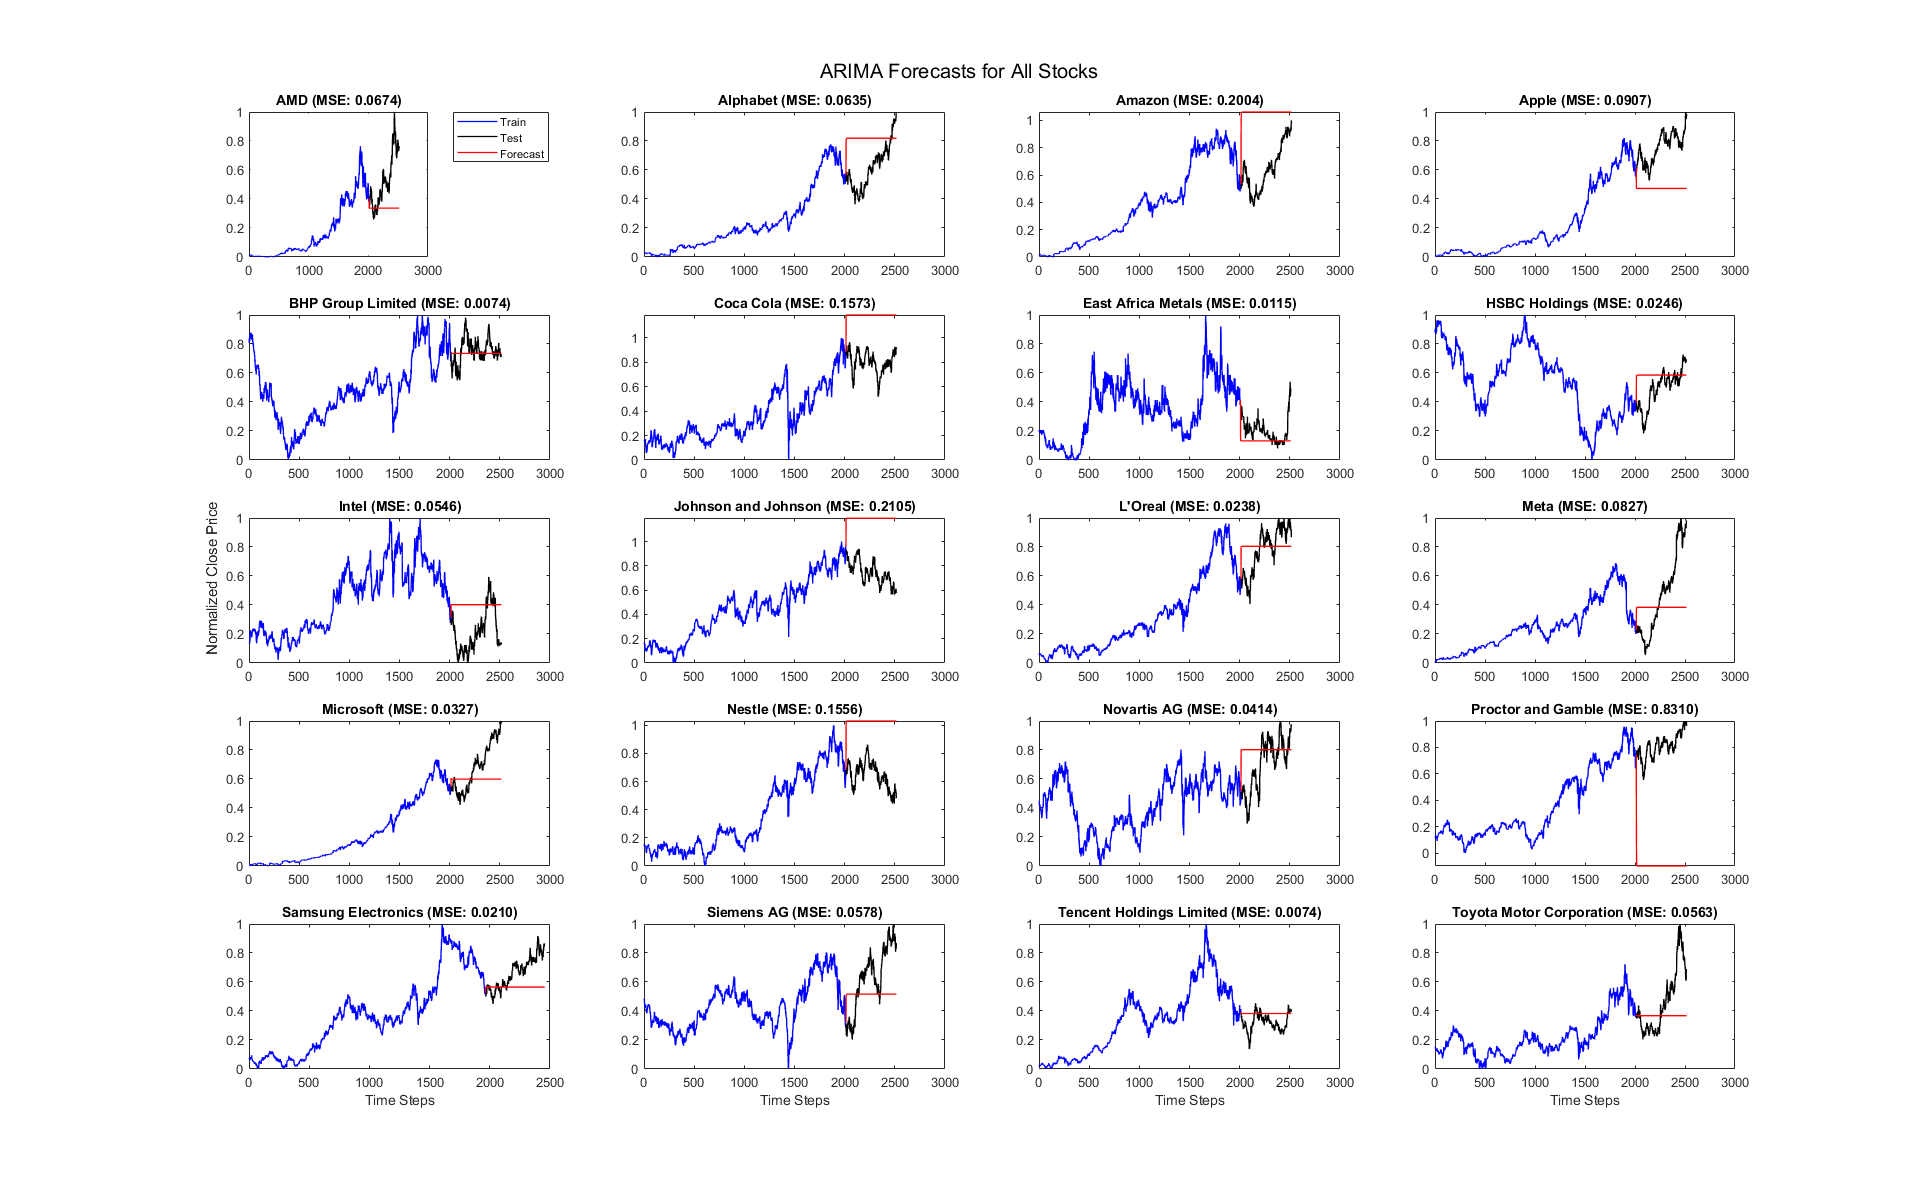

% Add a single y-label for all subplots
han = axes(gcf, 'visible', 'off'); 
han.Title.Visible = 'on';
han.XLabel.Visible = 'on';
han.YLabel.Visible = 'on';
ylabel(han, 'Normalized Close Price');

% Add a single legend outside the loop
legend(plotHandles, {'Train', 'Test', 'Forecast'}, 'Orientation', 'vertical', 'Location', 'bestoutside');

% Adjust subplot spacing and display the figure
sgtitle('ARIMA Forecasts for All Stocks');
set(gcf, 'Position', get(0, 'Screensize'));  % Maximize figure window

#### Table of Predictions

% Display results table
disp(resultsTable);

            StockName                MSE         MAE        MAPE 
    __________________________    _________    ________    ______

    "AMD"                          0.067437     0.19869    31.861
    "Alphabet"                      0.06349     0.22106    42.784
    "Amazon"                        0.20039     0.41621    75.811
    "Apple"                        0.090662     0.28389    36.332
    "BHP Group Limited"           0.0074288    0.065152    8.6765
    "Coca Cola"                     0.15731     0.38647    50.234
    "East Africa Metals"           0.011476    0.076453    30.908
    "HSBC Holdings"                0.024624     0.11659    33.662
    "Intel"                        0.054597     0.20659       Inf
    "Johnson and Johnson"           0.21052     0.44884    63.045
    "L'Oreal"                      0.023842      0.1274    18.956
    "

#### Average Performance Across Stocks

% Save results to CSV
writetable(resultsTable, 'ARIMA_Results.csv');

% Calculate and display average performance across all stocks
avgMSE = mean(resultsTable.MSE);
avgMAE = mean(resultsTable.MAE);
avgMAPE = mean(resultsTable.MAPE);

fprintf('\nAverage Performance Across All Stocks:\n');


Average Performance Across All Stocks:


fprintf('Average MSE: %.4f\n', avgMSE);

Average MSE: 0.1099


fprintf('Average MAE: %.4f\n', avgMAE);

Average MAE: 0.2475


fprintf('Average MAPE: %.2f%%\n', avgMAPE);

Average MAPE: Inf%



% Find best and worst performing stocks based on MSE
[bestMSE, bestIndex] = min(resultsTable.MSE);
[worstMSE, worstIndex] = max(resultsTable.MSE);

fprintf('\nBest Performing Stock (MSE): %s (MSE: %.4f)\n', resultsTable.StockName(bestIndex), bestMSE);


Best Performing Stock (MSE): Tencent Holdings Limited (MSE: 0.0074)


fprintf('Worst Performing Stock (MSE): %s (MSE: %.4f)\n', resultsTable.StockName(worstIndex), worstMSE);

Worst Performing Stock (MSE): Proctor and Gamble (MSE: 0.8310)


#### ARIMA Forecast Function

% Custom ARIMA forecast function definition

This MATLAB script performs time series analysis using ARIMA models for multiple stocks, normalizing the data and splitting it into training and testing sets. For each stock, the ARIMA(1,1,1) model is estimated using the training data, and future values are forecasted for the test period using a custom ARIMA forecast function. The script calculates error metrics (MSE, MAE, MAPE) for each stock, storing these in a results table. It then plots the actual and forecasted closing prices for each stock in subplots within a single figure. A legend is added, and the figure is maximized for better visibility. The results table is displayed and saved to a CSV file. Average performance metrics across all stocks are computed and printed, alongside identifying the best and worst performing stocks based on MSE. The custom ARIMA forecast function, defined at the end, handles the forecasting logic by applying AR and MA components and converting the forecasted differenced series back to the original scale.

#### **Best Performing Stock:**

**Tencent Holdings Limited (MSE: 0.0074)**

- **Interpretation**: The ARIMA model performed exceptionally well in forecasting the closing prices for Tencent Holdings Limited. An MSE of 0.0074 indicates that the model's predictions were very close to the actual observed values. This low error suggests that the ARIMA model was highly effective and accurate for this stock, capturing its price movements with minimal deviation.

#### **Worst Performing Stock:**

**Proctor & Gamble (MSE: 0.8311)**

- **Interpretation**: The ARIMA model did not perform well for Proctor & Gamble's stock data, as reflected by a high MSE of 0.8311. This large error value indicates that the model's predictions were significantly off from the actual observed values. The higher MSE suggests that the ARIMA model struggled to accurately capture the patterns and movements in Proctor & Gamble's stock prices, resulting in less reliable forecasts.

### Neural Network

#### Understanding Neural Networks

For forward propagation 4 equations are employed


$$\[
h = f(W_1 x + b_1)
\]

\[
\hat{y} = g(W_2 h + b_2)
\]

\[
f(z) = \max(0, z)
\]

\[
g(z) = \frac{1}{1 + e^{-z}}
\]$$


For back propagation another 4 equations are employed


$$\[
L = \frac{1}{2} \sum (y - \hat{y})^2
\]

\[
\frac{\partial L}{\partial \hat{y}} = \hat{y} - y
\]

\[
\frac{\partial \hat{y}}{\partial W_2} = h \cdot g'(W_2 h + b_2)
\]

\[
\frac{\partial \hat{y}}{\partial b_2} = g'(W_2 h + b_2)
\]$$


The gradients for the hidden layer are then computed


$$\[
\frac{\partial L}{\partial h} = \left(\frac{\partial L}{\partial \hat{y}}\right) \cdot W_2
\]

\[
\frac{\partial h}{\partial W_1} = x \cdot f'(W_1 x + b_1)
\]

\[
\frac{\partial h}{\partial b_1} = f'(W_1 x + b_1)
\]$$


The weight update rules are then defined


$$\[
W_2 = W_2 - \eta \frac{\partial L}{\partial W_2}
\]

\[
W_1 = W_1 - \eta \frac{\partial L}{\partial W_1}
\]
$$


The bias update rules are also computed


$$\[
b_2 = b_2 - \eta \frac{\partial L}{\partial b_2}
\]

\[
b_1 = b_1 - \eta \frac{\partial L}{\partial b_1}
\]$$


Once the weights and biases are applied this is repeated multiple times until the neural network matches the validation checks.

#### Training, Testing and Validation

The columns **Close** and **AdjClose** are excluded. Close and AdjClose are excluded because they are target columns and are interrelated. In this case, we are simulating a scenario where in the stock market at any moment one will be able to access the opening price, the current volume, the highest value up until that point and the lowest volume up until that point. This is the data that the model trains on. The model is thus able to predict if the price is going to go down or if it will go up in the next instance.

The code works by:

- Creating a table that will hold the MSE values that will be used for testing and validation.

- Iterating through each table to access the test/train and validation data.

- The **Close **column is extracted as it is the target column

- The Close, Date and AdjClose are removed from the general data.

- The data is then normalized

- The number of data points are computed and 75% of data is split to train the model while 25% is split to test the model.

- The neural network is defined as having 40 hidden nodes and the **feedforwardnet** neural network is utilised as the network of choice.

- The adam optimizer is set as the optimizer of choice with the maximum epochs being 1000. The training progress is also set to be shown.

- The neural network is trained and tested

- The Mean Squared Error (MSE) for testing is computed and stored in the table (after denormalizing the predicted values) created specifically for this purpose. It is also displayed.

- The predicted value is denormalized and the plotted against the actual value.

- The validation data is parsed and inputted into the neural network. 

- The predicted values are plotted against the actual values and the MSE is stored in the table created for this purpose.

- At the end of the iterations the table is written is to a CSV file.

Mean Squared Error: 0.0058593


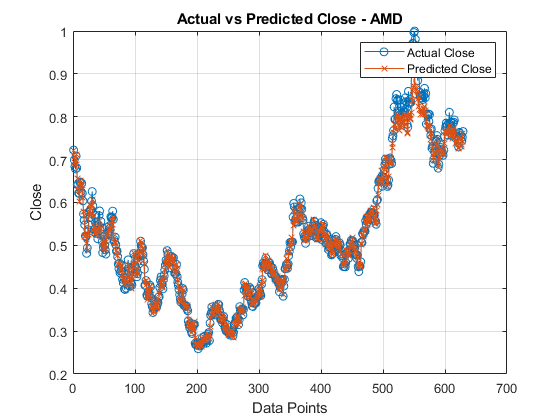

Validation Mean Squared Error: 0.011286


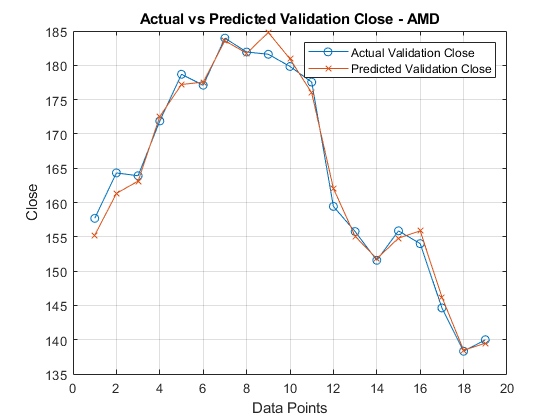

Mean Squared Error: 0.00086257


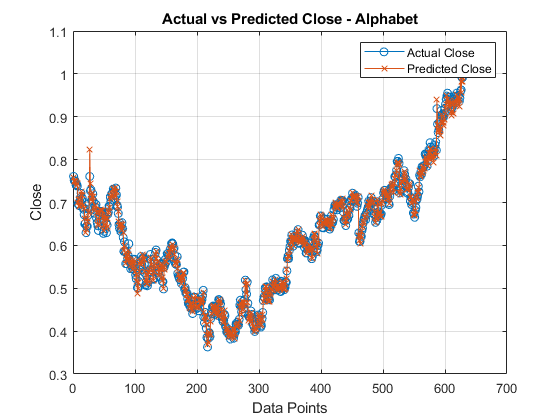

Validation Mean Squared Error: 0.036998


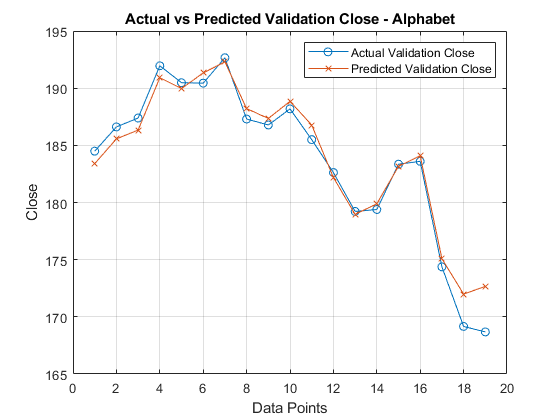

Mean Squared Error: 0.00083142


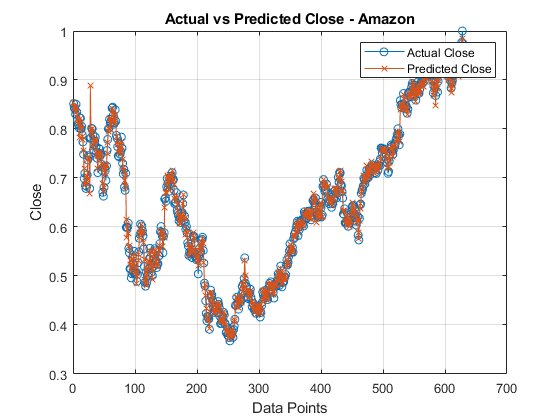

Validation Mean Squared Error: 0.041988


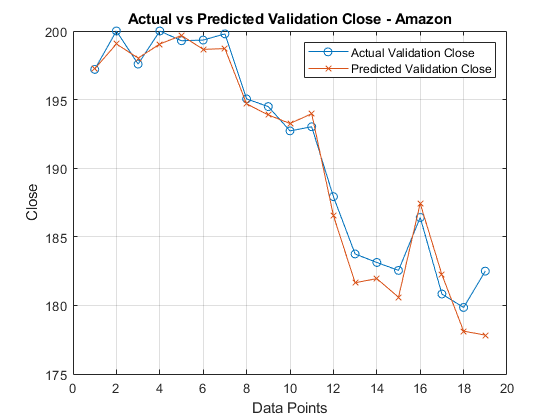

Mean Squared Error: 0.0074793


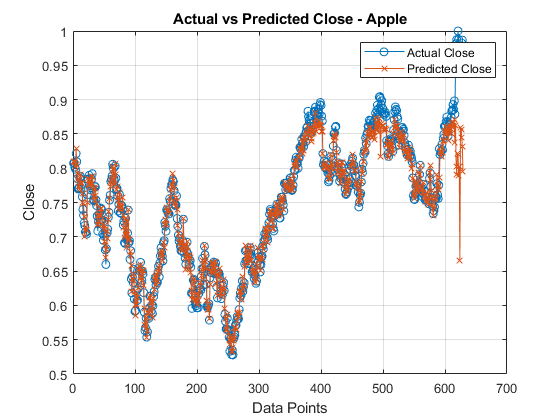

Validation Mean Squared Error: 0.044326


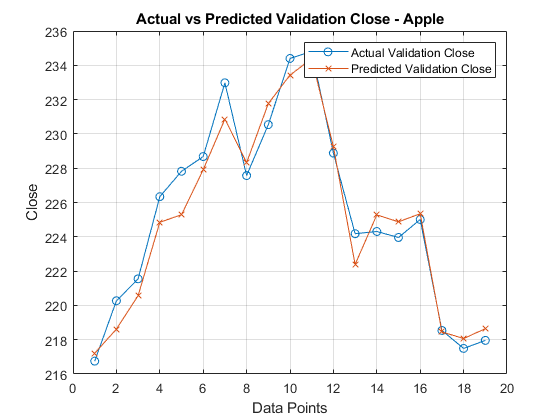

Mean Squared Error: 0.0012952


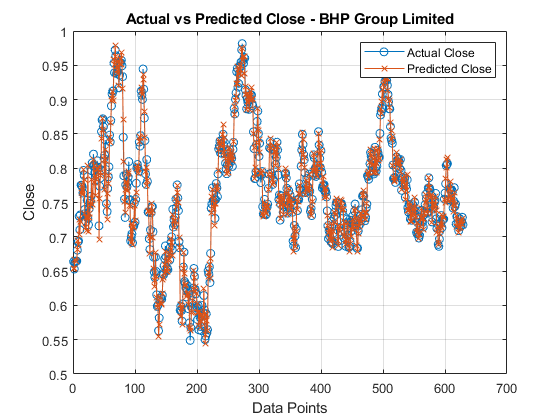

Validation Mean Squared Error: 0.015347


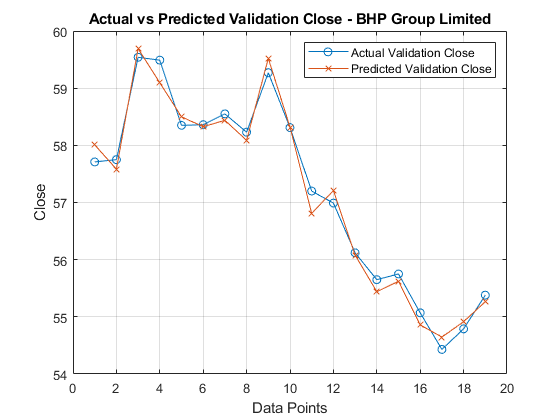

Mean Squared Error: 0.0066577


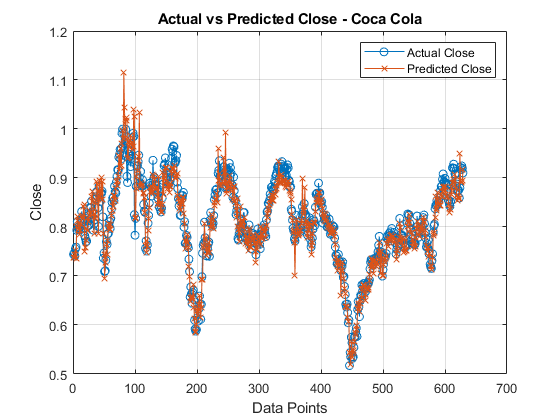

Validation Mean Squared Error: 0.051388


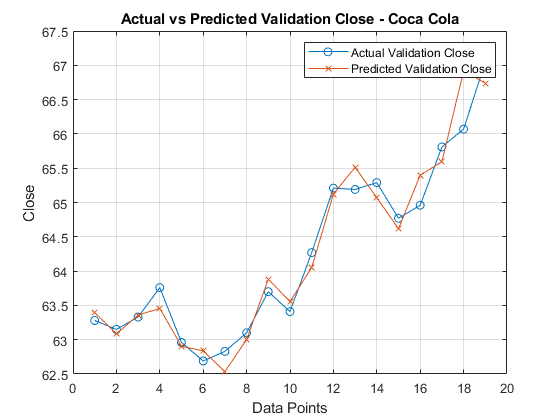

Mean Squared Error: 0.0030503


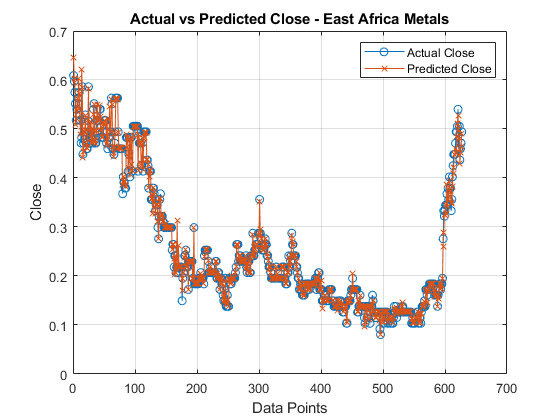

Validation Mean Squared Error: 0.48331


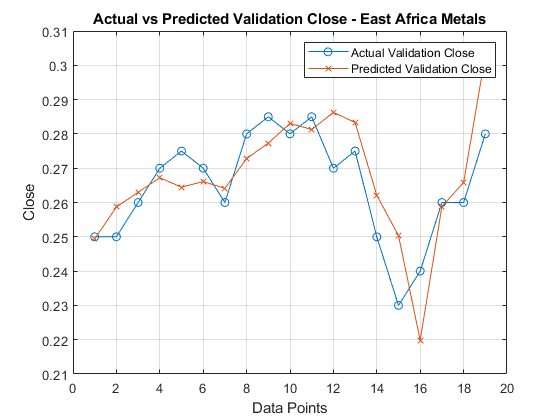

Mean Squared Error: 0.00028985


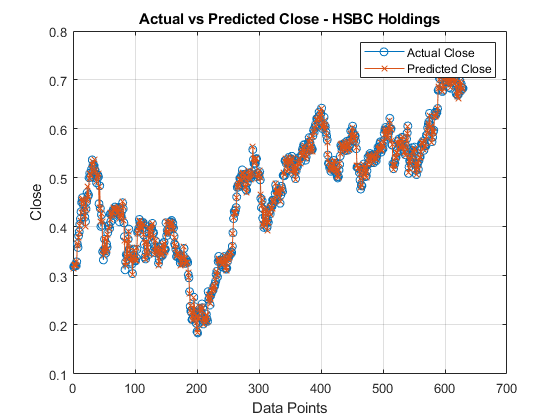

Validation Mean Squared Error: 0.10238


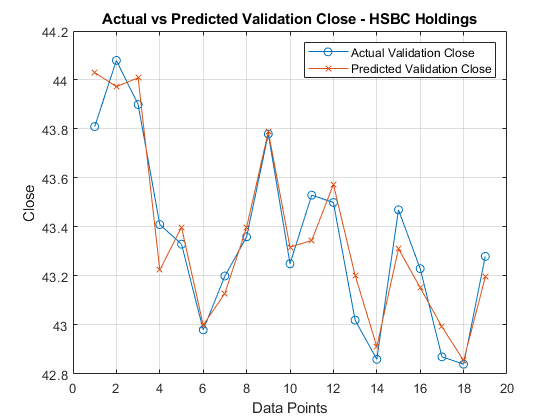

Mean Squared Error: 0.0011578


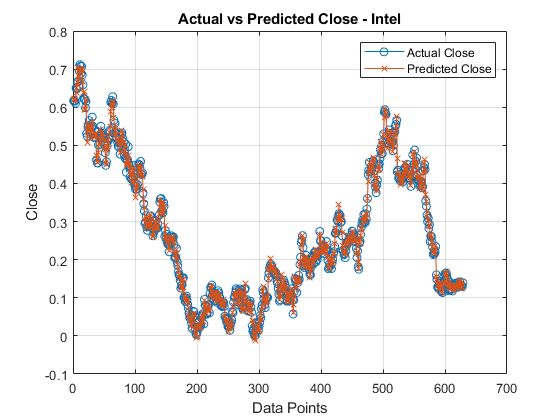

Validation Mean Squared Error: 0.072831


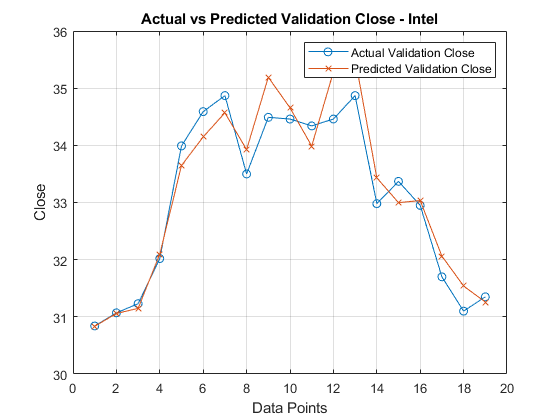

Mean Squared Error: 0.077928


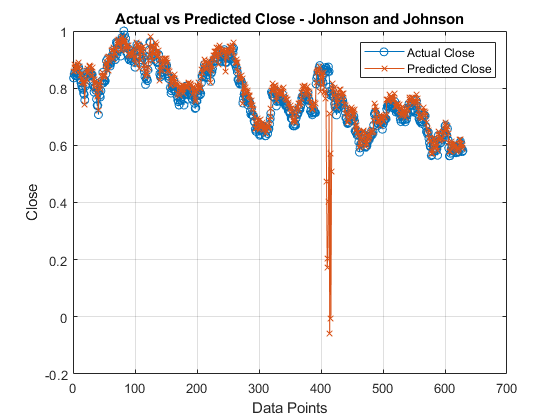

Validation Mean Squared Error: 0.049414


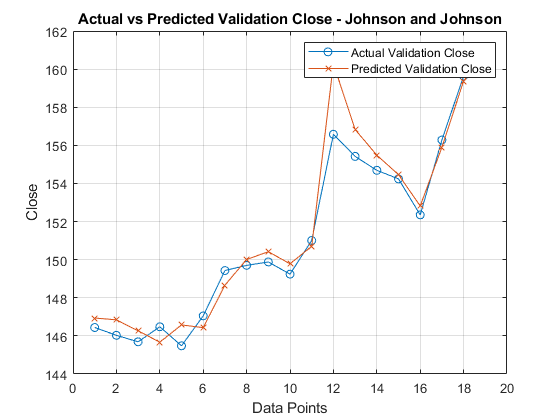

Mean Squared Error: 0.026


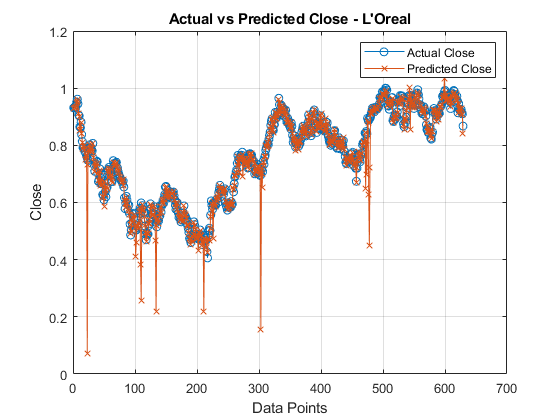

Validation Mean Squared Error: 0.17474


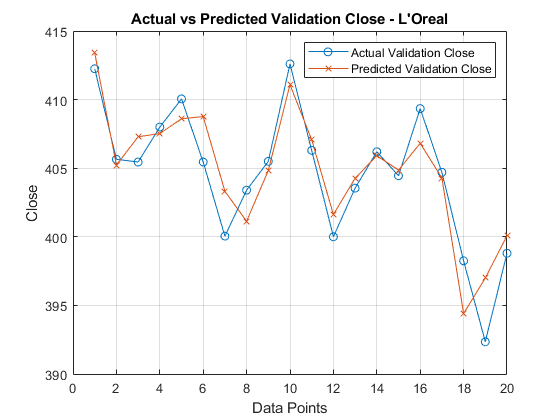

Mean Squared Error: 0.12349


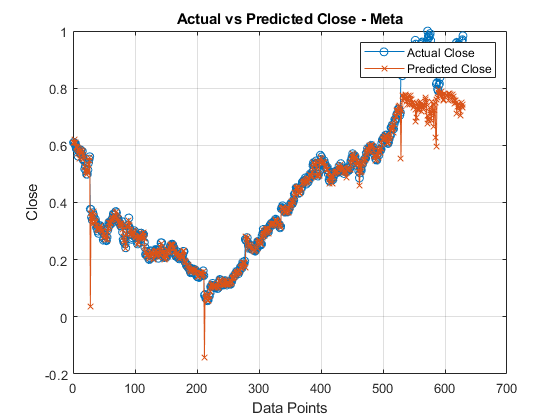

Validation Mean Squared Error: 0.028277


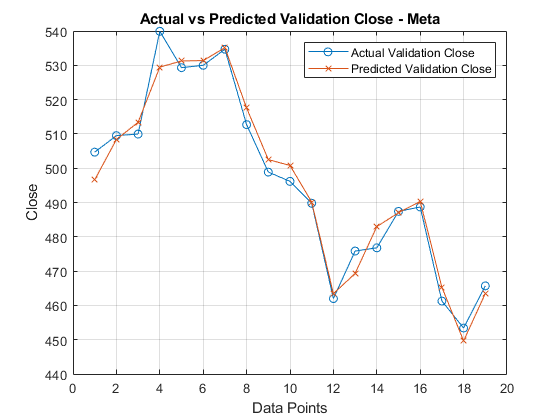

Mean Squared Error: 0.041602


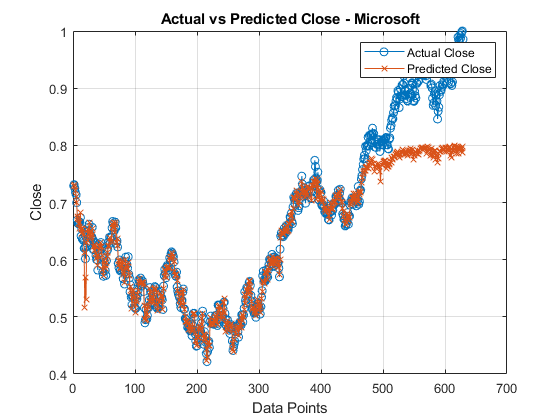

Validation Mean Squared Error: 0.024886


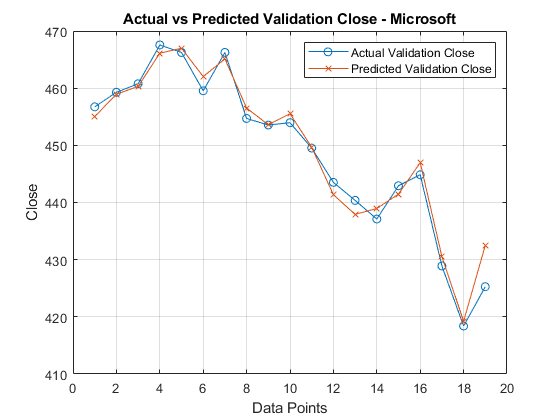

Mean Squared Error: 0.00094534


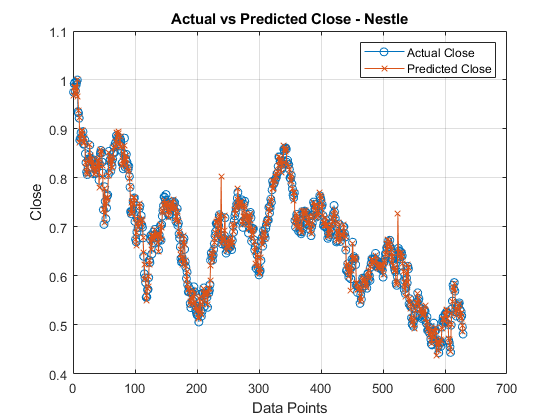

Validation Mean Squared Error: 0.049855


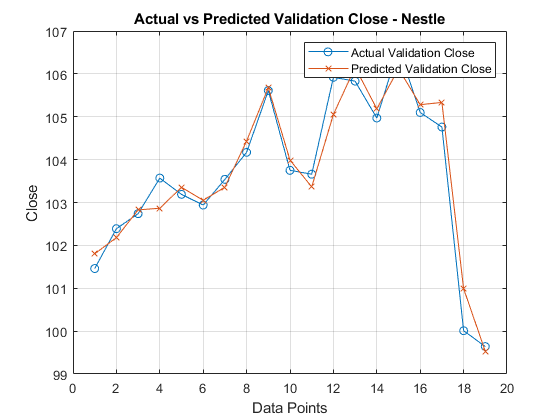

Mean Squared Error: 0.0075997


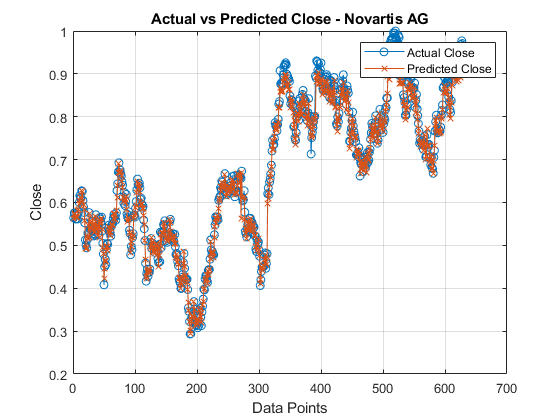

Validation Mean Squared Error: 0.028158


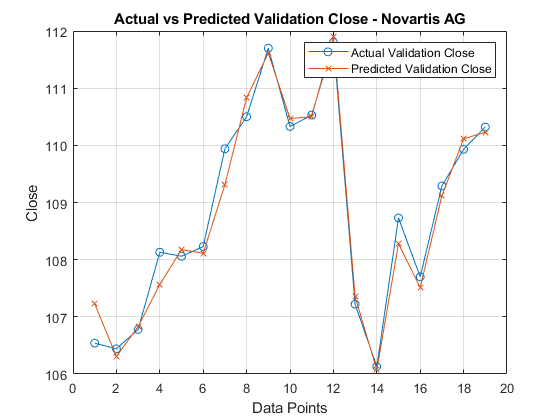

Mean Squared Error: 0.0012072


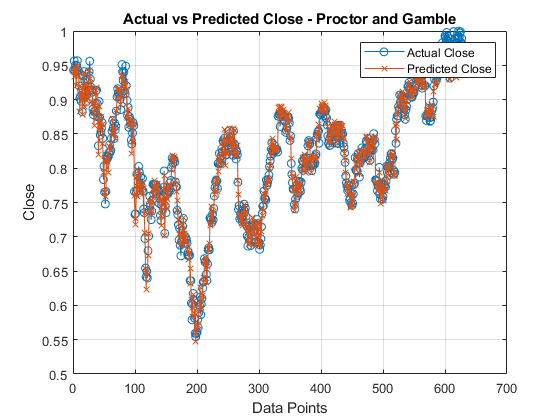

Validation Mean Squared Error: 0.12629


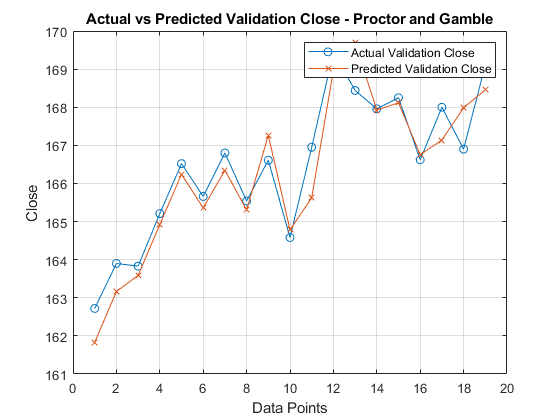

Mean Squared Error: 0.00038486


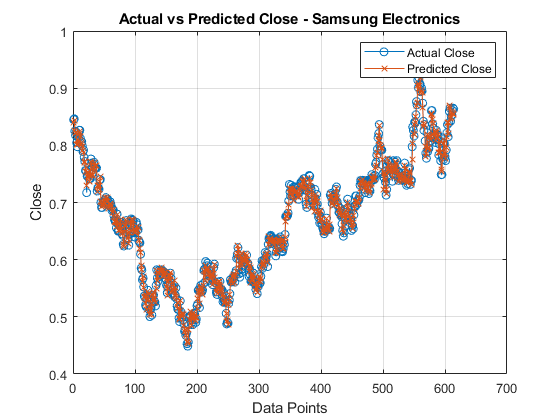

Validation Mean Squared Error: 0.020738


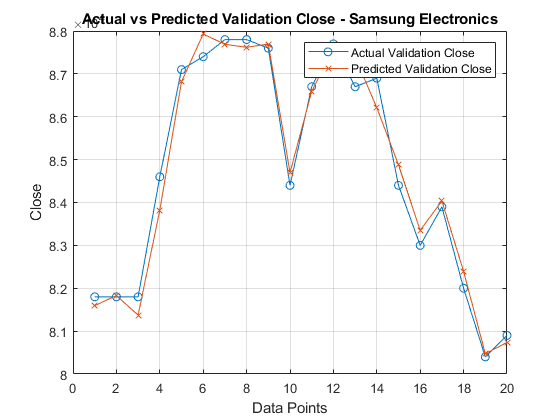

Mean Squared Error: 0.021622


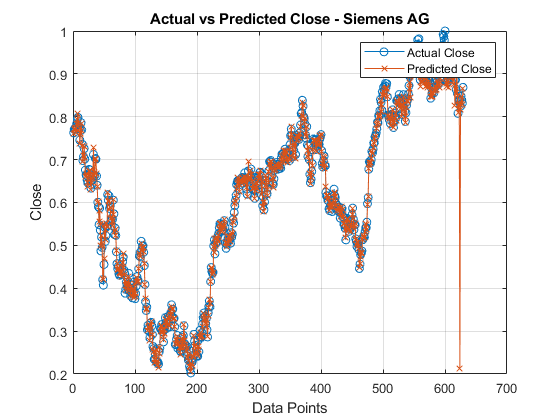

Validation Mean Squared Error: 0.15439


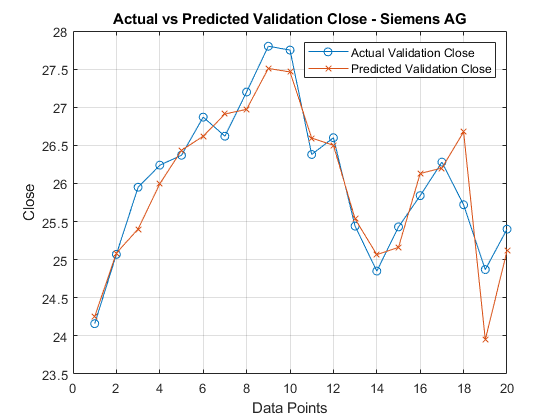

Mean Squared Error: 0.00032849


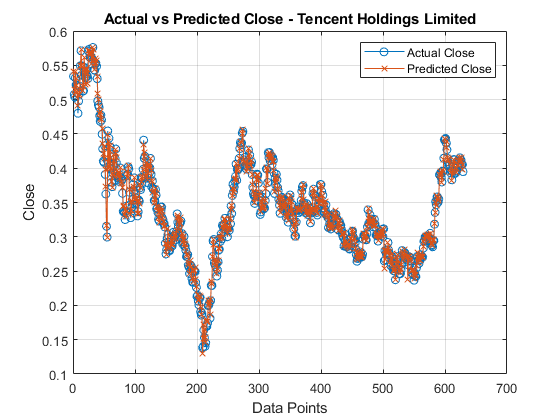

Validation Mean Squared Error: 0.01493


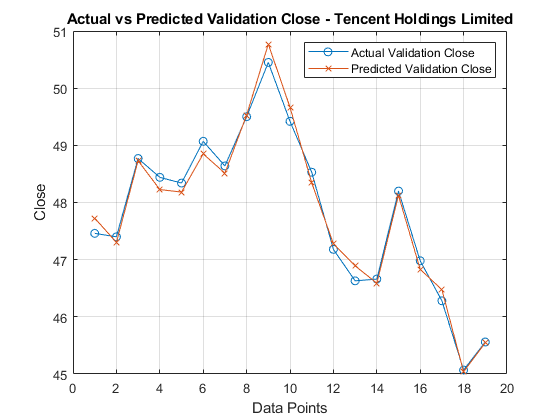

Mean Squared Error: 0.15614


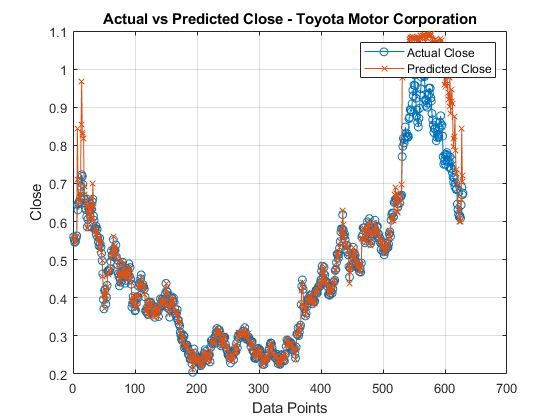

Validation Mean Squared Error: 0.017593


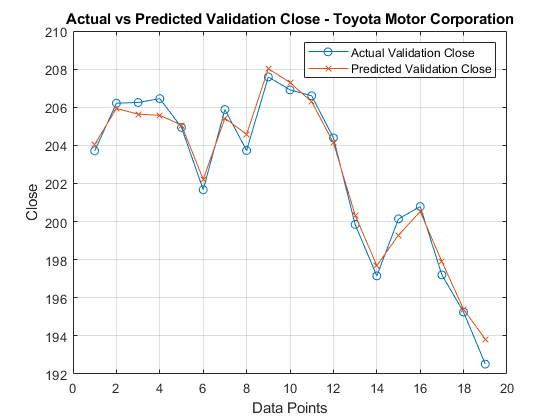

% Create an empty table to store MSE values
resultsTable = table('Size', [numel(allData), 2], 'VariableTypes', {'string', 'double'}, 'VariableNames', {'FileName', 'MSE'});

% Loop over each table in allData
for k = 1:numel(allData)
    data = allData{k};
    
    % Extract the Close variable as the target
    target = data.Close;
    
    % Remove Date and Close columns as they are not needed for prediction
    data(:, {'Date', 'Close', 'AdjClose'}) = [];
    
    % Convert table to matrix
    data = table2array(data);
    
    % Normalize data (optional but often recommended for neural networks)
    data_normalized = normalize(data);
    target_normalized = normalize(target);
    
    % Number of data points
    num_data = size(data, 1);
    
    % Split ratio (e.g., 75% training, 25% testing)
    train_ratio = 0.75;
    train_size = round(train_ratio * num_data);
    
    % Training data
    train_data = data_normalized(1:train_size, :);
    train_target = target_normalized(1:train_size, :);
    
    % Testing data
    test_data = data_normalized(train_size+1:end, :);
    test_target = target_normalized(train_size+1:end, :);
    
    % Define the neural network architecture
    hidden_layer_size = 40;
    net = feedforwardnet(hidden_layer_size);
    
    % Set training options
    train_options = trainingOptions('adam', ...  % Use Adam optimizer (or other optimizer)
        'MaxEpochs', 1000, ...  % Number of epochs to train
        'Verbose', true, ...   % Show training progress
        'Plots', 'training-progress');  % Show training progress plot
    
    % Train the neural network with specified options
    [net, tr] = train(net, train_data', train_target', [], [], [], [], [], [], train_options);
    
    % Predict on test data
    predictions = net(test_data');
    
    % Measure the performance (e.g., Mean Squared Error)
    clear mse;
    neural_mse = mse(predictions - test_target');
    clear mse;
    disp(['Mean Squared Error: ', num2str(neural_mse)]);
    
    % Denormalize the predicted values
    predicted_close = predictions' * std(target) + mean(target);
    actual_close = target(train_size+1:end);
    
    % Get the file name (without extension)
    [~, fileName, ~] = fileparts(csvFiles(k).name);
    
    % Add the MSE to the results table
    resultsTable(k, 1) = {fileName};
    resultsTable(k, 2) = {neural_mse};
    
    % Plotting with title including file name
    figure;
    plot(actual_close, '-o', 'DisplayName', 'Actual Close');
    hold on;
    plot(predicted_close, '-x', 'DisplayName', 'Predicted Close');
    hold off;
    xlabel('Data Points');
    ylabel('Close');
    title(['Actual vs Predicted Close - ', fileName]);
    legend;
    grid on;
    
    % Validate on the validation data
    validation_data = validationData{k};
    validation_target = validation_data.Close;
    validation_data(:, {'Date', 'Close', 'AdjClose'}) = [];
    validation_data = table2array(validation_data);
    
    validation_data_normalized = normalize(validation_data);
    validation_target_normalized = normalize(validation_target);
    
    validation_predictions = net(validation_data_normalized');
    
    % Calculate MSE for validation data
    clear mse;
    validation_mse = mse(validation_predictions' - validation_target_normalized);
    clear mse;
    disp(['Validation Mean Squared Error: ', num2str(validation_mse)]);
    
    % Add the validation MSE to the results table
    resultsTable{k, 3} = validation_mse;
    
    % Denormalize validation predicted values
    validation_predicted_close = validation_predictions' * std(validation_target) + mean(validation_target);
    actual_validation_close = validation_target;
    
    % Plotting validation data
    figure;
    plot(actual_validation_close, '-o', 'DisplayName', 'Actual Validation Close');
    hold on;
    plot(validation_predicted_close, '-x', 'DisplayName', 'Predicted Validation Close');
    hold off;
    xlabel('Data Points');
    ylabel('Close');
    title(['Actual vs Predicted Validation Close - ', fileName]);
    legend;
    grid on;
end


writetable(resultsTable, 'FNN_MSE.csv');

### Custom Functions

#### Custom ARIMA Forecast

function forecast = customARIMAForecast(model, y, numSteps)
    forecast = zeros(numSteps, 1);
    
    % Extract model parameters
    ar_coeff = cell2mat(model.AR);
    ma_coeff = cell2mat(model.MA);
    constant = model.Constant;
    
    % Prepare differenced series
    dy = diff(y);
    
    for t = 1:numSteps
        % AR component
        ar_term = ar_coeff * dy(end);
        
        % MA component
        if t == 1
            ma_term = ma_coeff * (dy(end) - ar_term);
        else
            ma_term = ma_coeff * (forecast(t-1) - ar_term);
        end
        
        % Forecast differenced series
        forecast_d = constant + ar_term + ma_term;
        
        % Convert back to original scale
        forecast(t) = y(end) + forecast_d;
        
        % Update dy for next iteration
        dy = [dy; forecast_d];
    end
end